# **Programa para calcular el Flujo Magnético en el interior de un Núcleo Ferromagnético generado por una bobina con alimentación Senoidal**

**Autor: Ph D. Jaime Antonio González Castellanos, Universidad Francisco de Paula Santander, Cúcuta, Colombia**

## Resumen

La presente actividad muestra en forma simple y detallada la implementación, a partir de las ecuaciones básicas de campos electromagnéticos, de una metodología para calcular el  flujo magnético generador por una espira cuando es alimentada con una corriente continua en el interior de un núcleo ferromagnético.

## Objetivos de Aprendizaje

- Determinar el Flujo magnético generado por una bobina en el interior de un núcleo ferromagnético

- Establecer las ecuaciones necesarias para la implementación del ejercicio

- Calcular las Reactancias del circuito

## Antes de Comenzar 

Esnecesario establecer el problema a ser resuelto basado en:

- Ecuaciones a ser utilizadas

- Tipo de Material ferromagnético

- Geometría del Núcleo

$\oint H*dl = N*i$    Ley de Ampere

$$\mathcal{F} = N*i$              Fuerza Magnetomotriz

$\Re = \frac{\mathcal{F}}{\phi}$                   Reluctancia

$\mu = \mu_0*\mu_r$              permeabilidad magnética

Para la obtención de las caraterísticas del material ferromagnético es posible usar dos formasÑ

- Tablas

- Curvas

Se usarán tablas para este caso

La geometría del núcleo ferromagnético será la siguiente:

 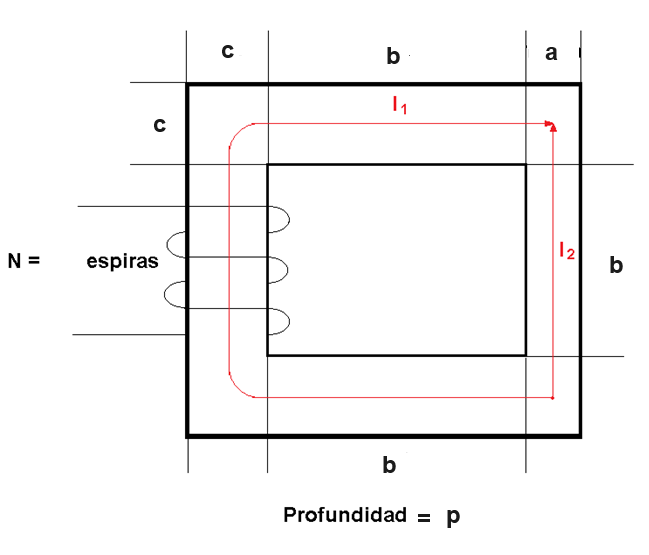

## Sección 1: Carga de Datos

a continuación se hce la carga de datos con la información preliminar que se tiene

a = 10;              % longitud del lado a en (cm)
b = 30;              % longitud del lado b en (cm)
c = 20;              % longitud del lado c en (cm)
p = 20               % Profundidad en (cm)  

p = 20

miur = 3500          % Permeabilidad relativa

miur = 3500

miu0 = 4*pi*1e-7;    % permeabilidad de Vacío en (H/m)
N = 300;             % Número de vueltas de la bobina (espiras) 
I = 2;               % Corriente I en (A)

## Sección 2: Cálculo de las Distancias lc en (m)

A partir de las dimensiones del núcleo se procede a determinar los recorridos 

lc1 = (0.5*a +b+c+b+c+b+0.5*a)/100       %Longitud del primer recorrido en (m)

lc1 = 1.4000

lc2 = (0.5*c+b+0.5*c)/100

lc2 = 0.5000

## Sección 3: Cálculo de las Áreas (m^2)

Se determinan las áreas:


A1 = (p*c)/10000

A1 = 0.0400


A2 = (p*a)/10000

A2 = 0.0200

## Sección 4: Cálculo de las Reluctancias y Relectancia Equivalente

miu = miur*miu0

miu = 0.0044

Rel1 = lc1/miu/A1

Rel1 = 7.9577e+03

Rel2 = lc2/miu/A2

Rel2 = 5.6841e+03

Relq= Rel1+Rel2

Relq = 1.3642e+04

## Sección 5: Cálculo de la Fuerza Magnetomotriz F en Amperios-Vuelta 


F = N*I

F = 600

## Sección 6: Calculo del Flujo Magnético Flujo (Wb)


Flujo = F/Relq

Flujo = 0.0440

## Recursos Adicionales

- Tutorial de Matlab 

- Cursos de Campos electromagéticos

## Referencias 

- M. N. O. Sadiku, *Principles of Electromagnetics*, 6th ed., Oxford University Press, 2014

- P. C. Krause, O. Wasynczuk, S. D. Sudhoff, and S. Pekarek, *Analysis of Electric Machinery and Drive Systems*, 3rd ed., Wiley-IEEE Press, 2013

- M. N. O. Sadiku, *Principles of Electromagnetics*, 6th ed., Oxford University Press, 2014

- J. D. Jackson, *Classical Electrodynamics*, 3rd ed., Wiley, 1998.

- Material del profesor 